# Experiment with LSTMpathToEEG model(3 channels)

## Load data

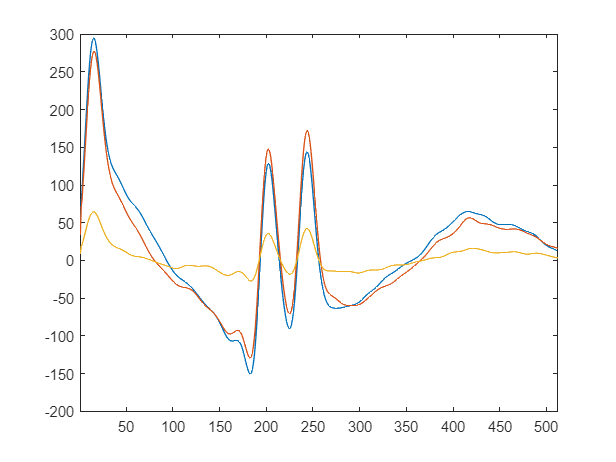

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

maxEpochs = 30;
optimVars = [
    %miniBatchSize,learningrate,numBlocks,numHiddenUnits;
    optimizableVariable('miniBatchSize',[2 16],'Type','integer')%[8 128]
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")
    optimizableVariable('numBlocks',[1 8],'Type','integer')%[1 5]
    optimizableVariable('numHiddenUnits',[1 300],'Type','integer')];

objectFunction = objectFunctionLSTM(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  10*60*60, ...
                        'Verbose',                  0,...
                        "UseParallel",              true,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);

mkdir('OptVars');
save("OptVars\LSTMoptVars.mat","optVars","-mat");


    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');